# Euler Rats

Demonstrate operation with a function call graph.

We have three pieces of code.

- This (live) script - the main script.

- The solver (euler.m), that we'll call from the main script.

- The rate function (rat_rate.m), that the solver will call.

Make sure all these files are in the same path (the same directory, and the same as the current working directory of the Command Window.)

We'll include break points, step and step-into to follow the flow.

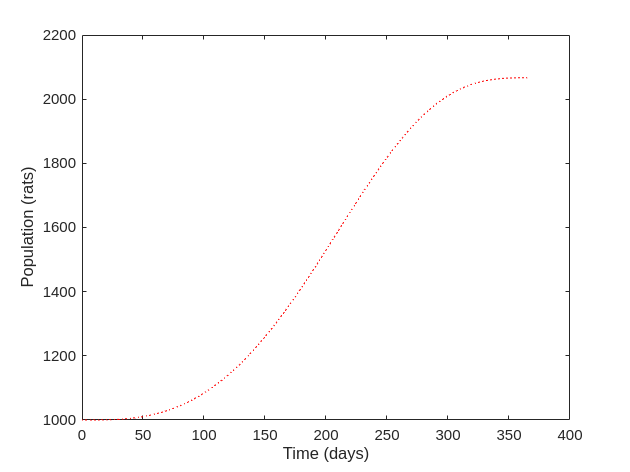

% Initial condition
rats_init = 1000; 
% Time span
t_span = [0, 365];

[tte, rats_euler] = euler(@rat_rate, t_span, rats_init);

figure(1);
clf()
plot(tte, rats_euler, "r:")
xlabel('Time (days)')
ylabel('Population (rats)')

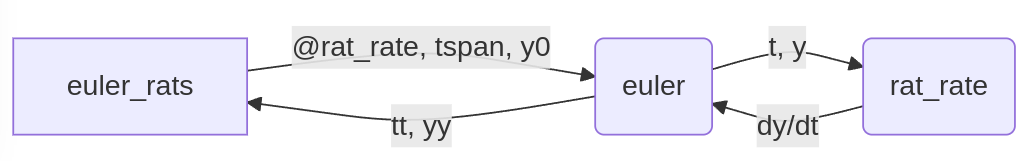

Mermaid script

`flowchart` `LR`

    `A``[euler_rats]` `-->``|@rat_rate, tspan, y0|` `B``(euler)`

    `B` `-->` `|t, y|``C``(rat_rate)`

    `C` `-->` `|dy/dt|``B`

    `B` `-->` `|tt, yy|` `A`